# Bifurcation diagram for a Y-shaped quantum graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

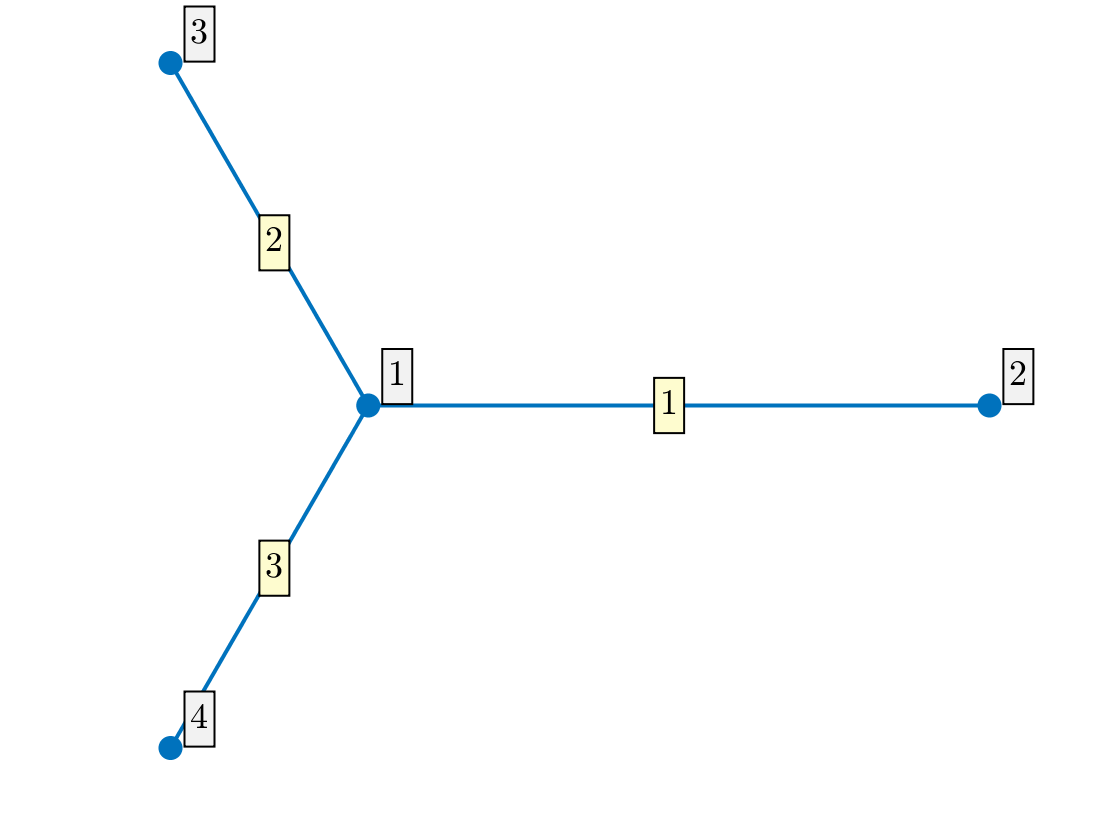

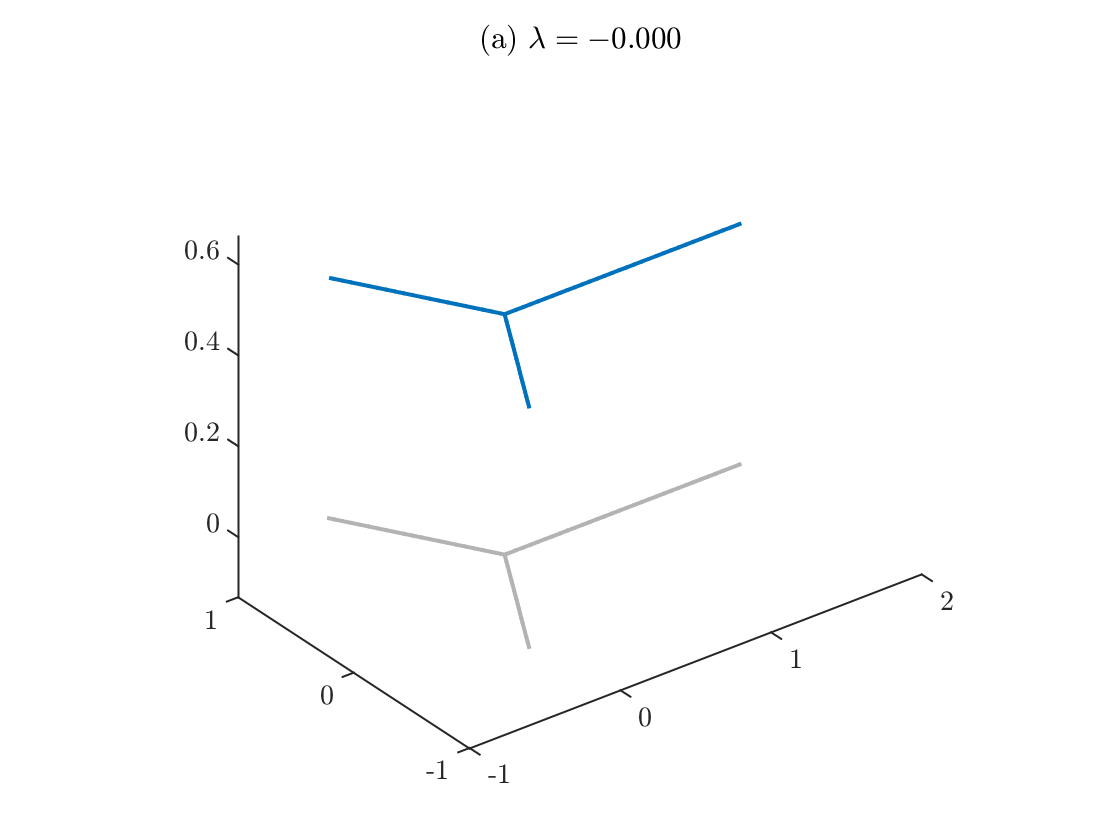

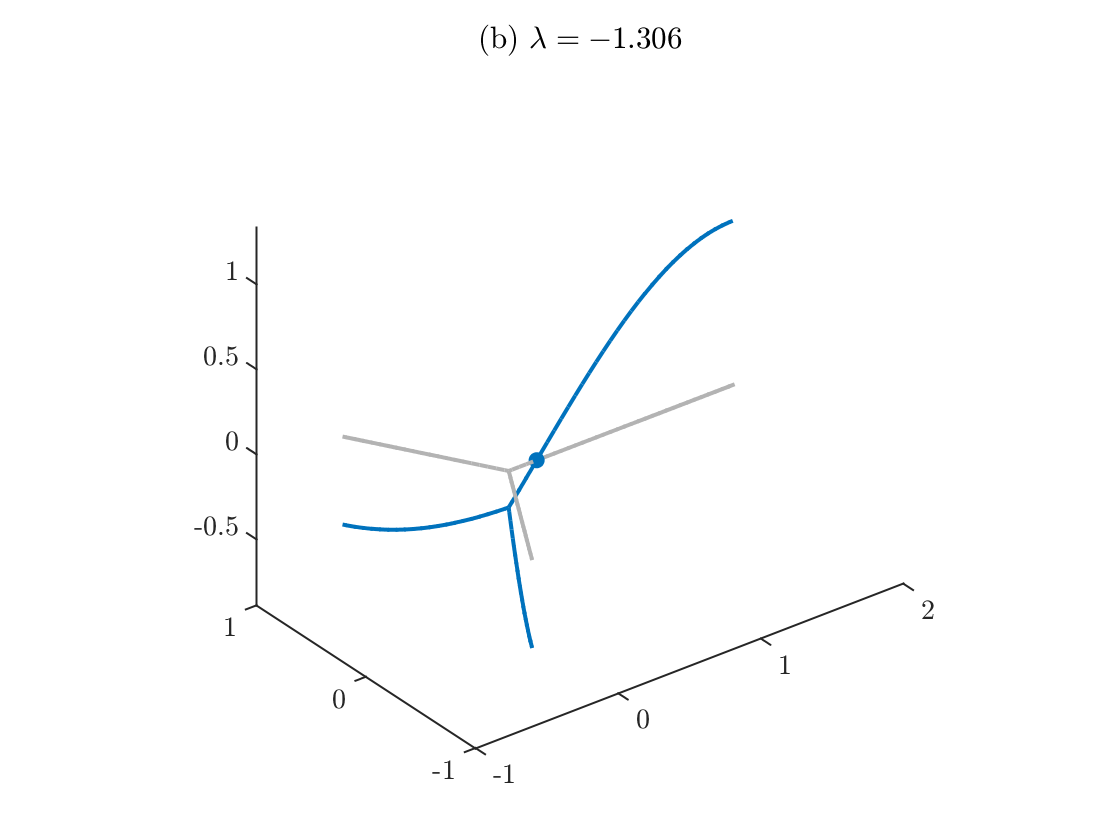

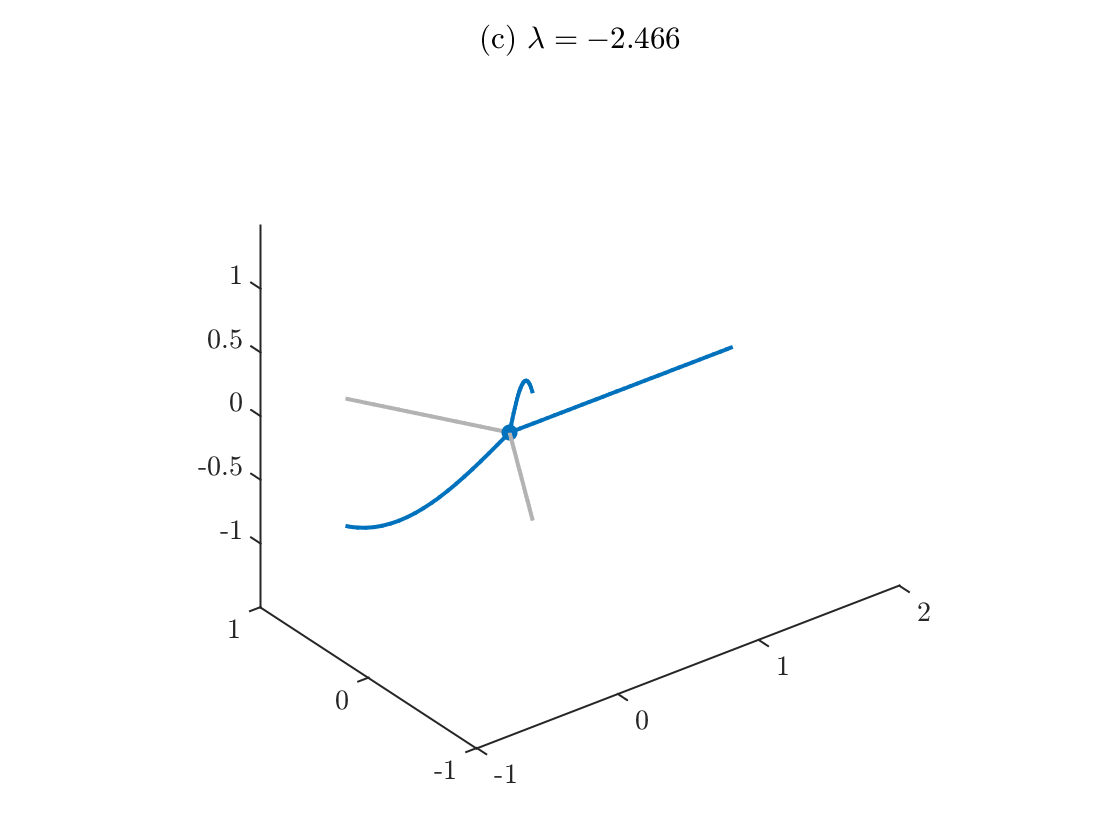

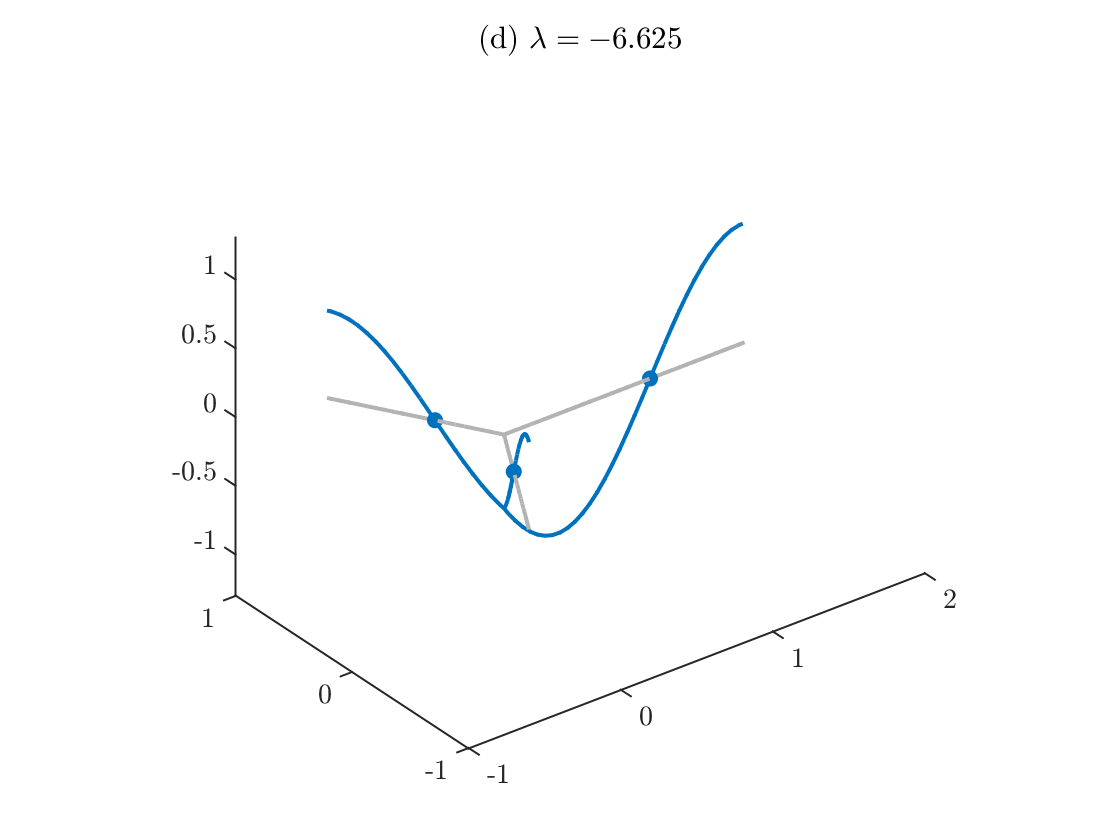

Saved to directory data/star/003.
Run number is 3.


tag='star';
LVec=[pi/2 1 1]; % Nonresonant lengths chosen to exclude double eigenvalues
Phi = quantumGraphFromTemplate(tag,'LVec',LVec);

nToPlot=4;
nDoubles=2;
nTriples=0;

diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

The two outputs of `continuefromEig` are

- `bn1` The branch number

- `bl1` A vector containing the locations on the branch where bifurcations occur and labeling the type of the bifurcation

options=continuerSet([],'LambdaThresh',-2,'NThresh',4,'plotFlag',false,'maxTheta',1.5);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

Lambda threshold crossed.
Branch number 1.
Data saved to directory data/star/003/branch001.
Branching Bifurcation at solution number 20.
Branching Bifurcation at solution number 27.


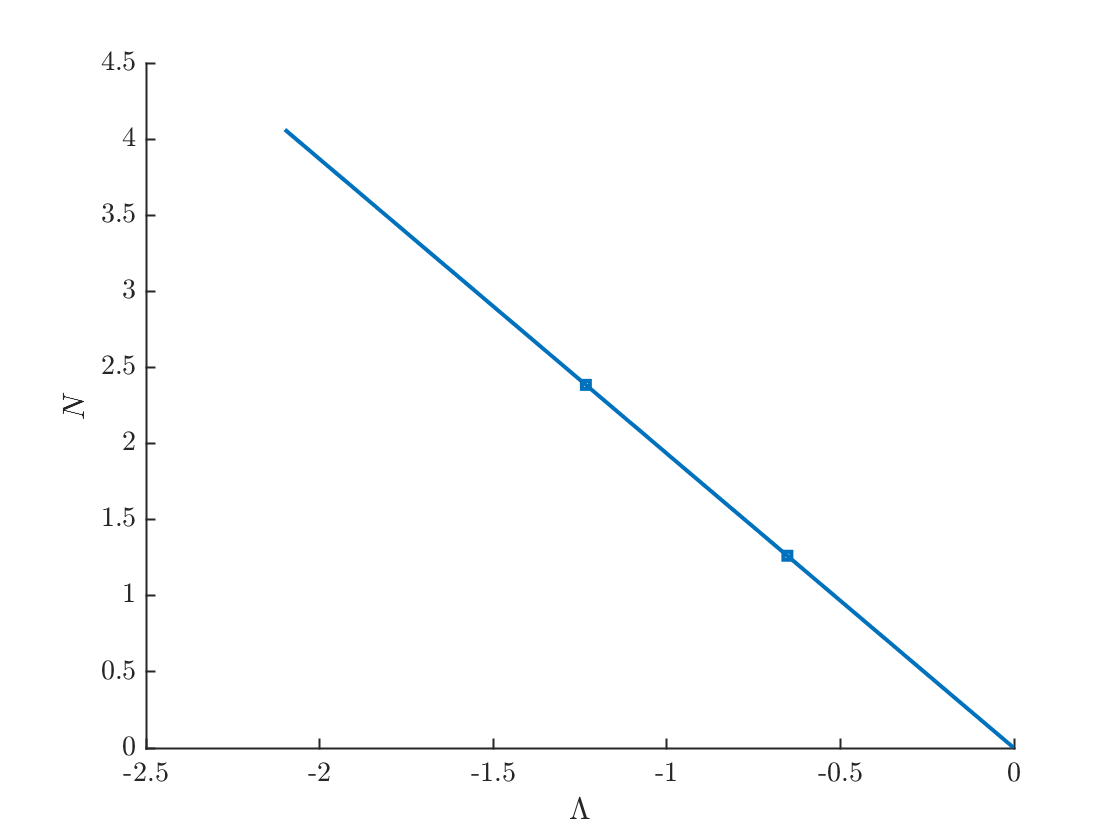

bifurcationDiagram(tag,diagramNumber)

## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/star/003/branch002.
No branching bifurcations found.


[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),-1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/star/003/branch003.
Branching Bifurcation at solution number 14.


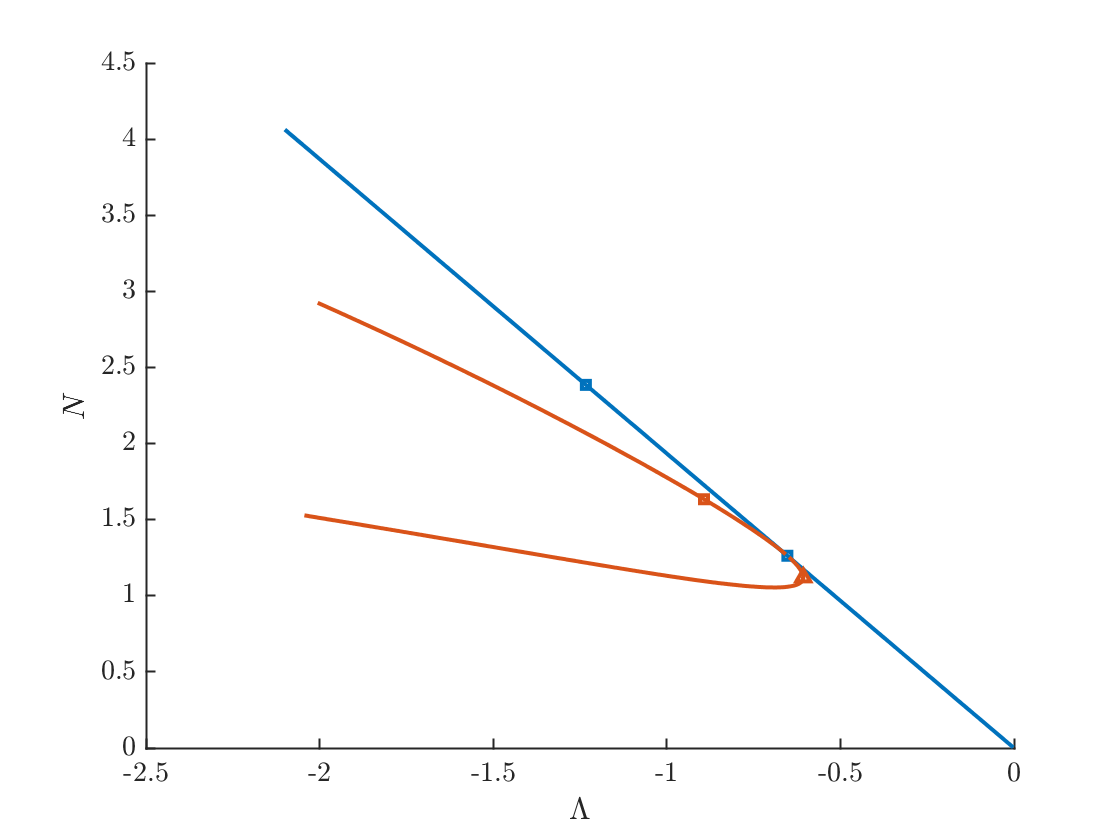

bifurcationDiagram(tag,diagramNumber)

- The function `continueFromBranchpoint` continues a branch from the second branching bifurcation point. Since this is a pitchfork bifurcation, we need to continue in just one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/star/003/branch004.
No branching bifurcations found.


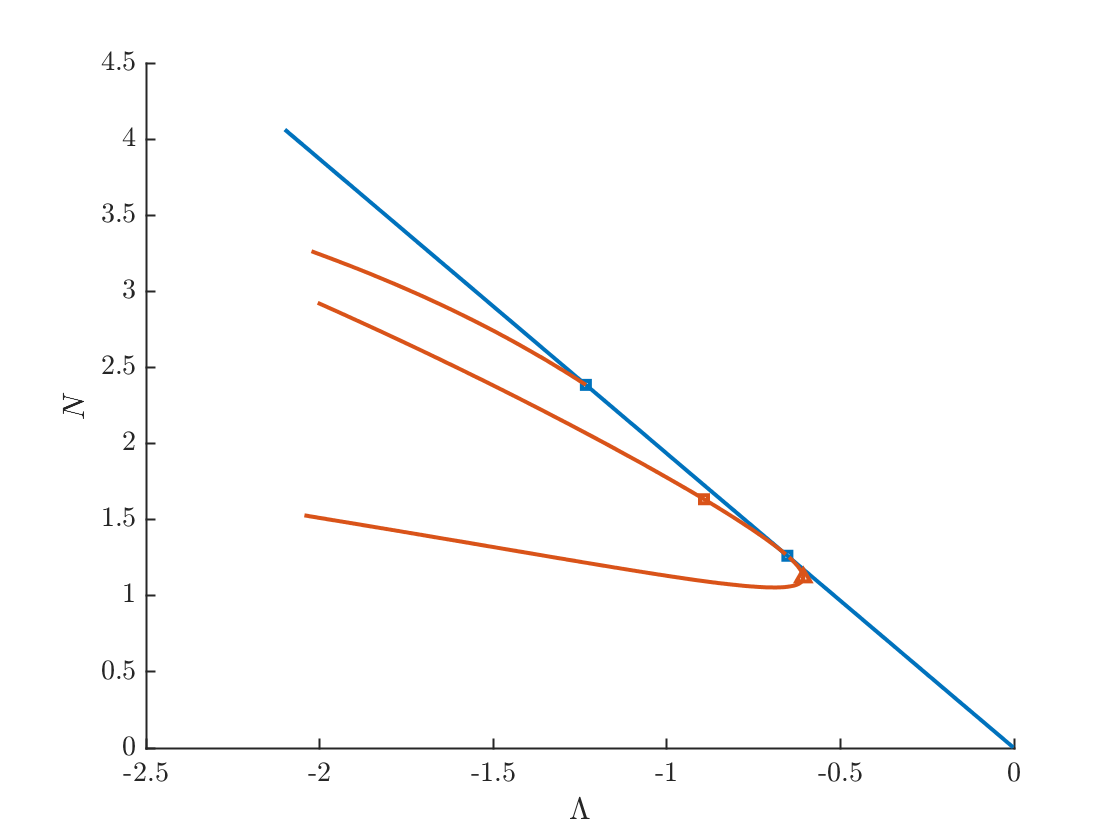

bifurcationDiagram(tag,diagramNumber)

## Compute a branch that bifurcates from the second branch

Continues from the branch stored in `bn3` from the bifurcation point at `bl3(1)`. This bifurcation breaks the symmetry in branches two and three.

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/star/003/branch005.
No branching bifurcations found.


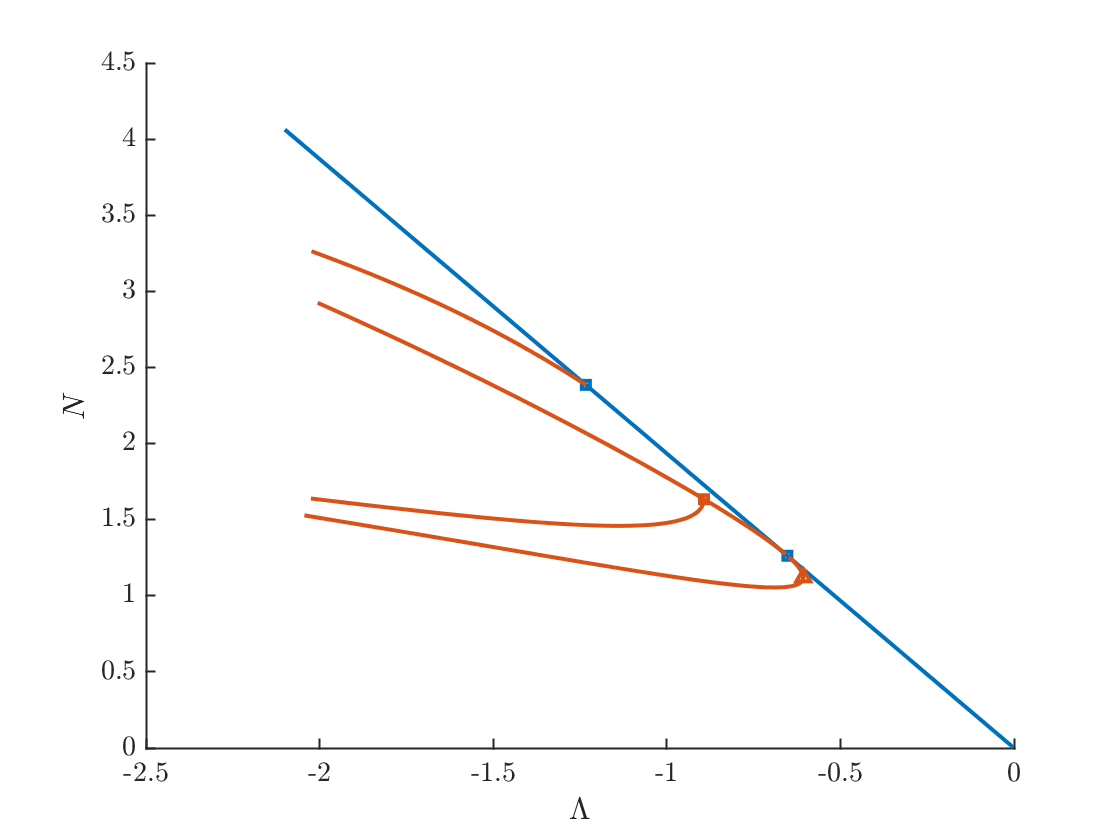

bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

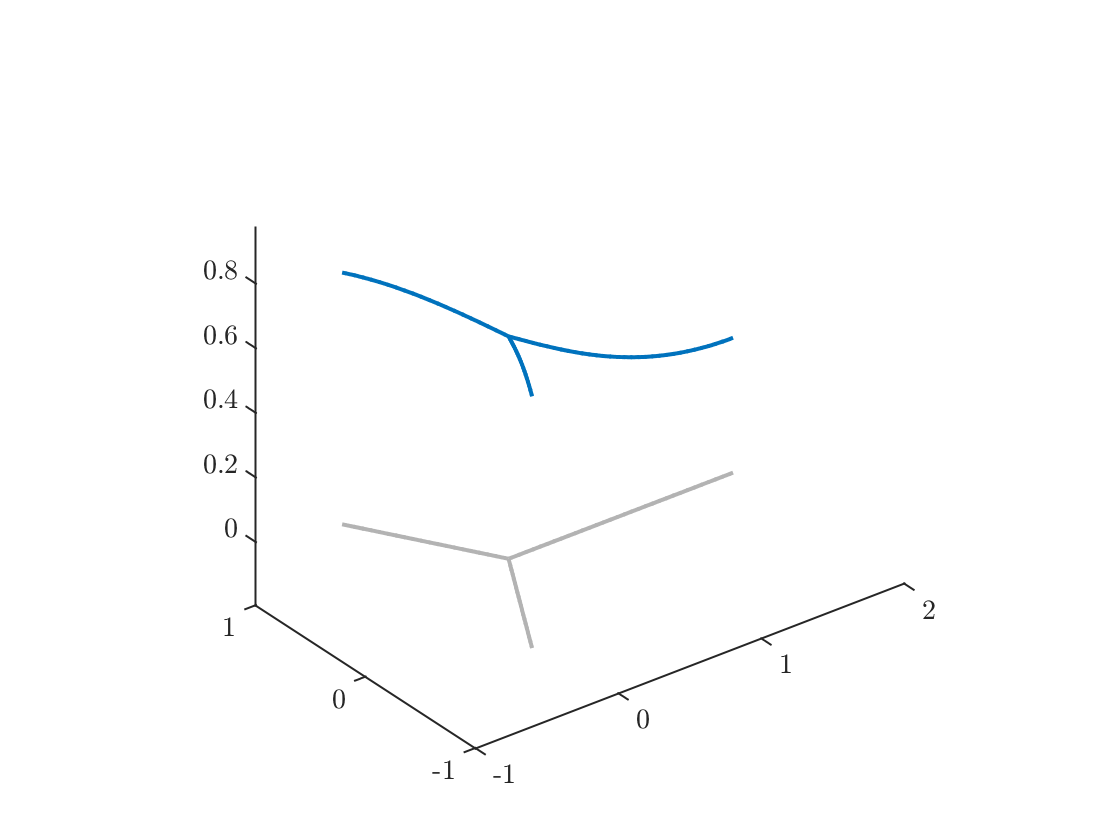

plotSolution(tag,diagramNumber,bn3,15)

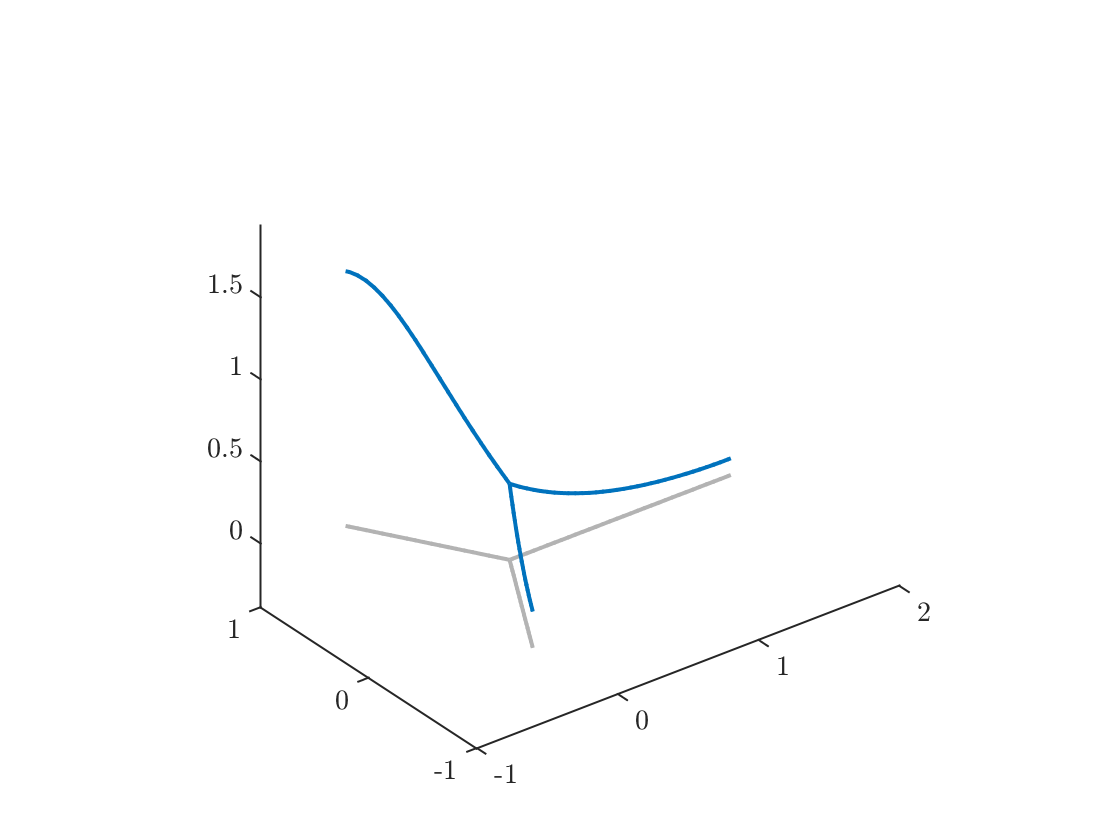

plotSolution(tag,diagramNumber,bn5,'last')